eqa = importdata('..//..//temp//simu86400//eqa_86400.txt'); 
diff_eqa = diff(eqa, 1, 1); diff_diff_eqa = diff(diff_eqa, 1, 1); diff_diff_diff_eqa = diff(diff_diff_eqa, 1, 1); diff_diff_diff_diff_eqa = diff(diff_diff_diff_eqa, 1, 1);
eqb = importdata('..//..//temp//simu86400//eqb_86400.txt'); diff_eqb = diff(eqb);

pc_a = [1.50; 0.00004; 0.00004];
pc_b = [1.50; 0.00004; 0.00004];

t = 0: 5: 86400 - 5;
alt_angle_sin = deg2rad(2 + 1 * sin(2 * pi / 250 * t))';
phase_centre_simu = pc_a(1) + pc_b(1) * cos(alt_angle_sin) - pc_b(3) * sin(alt_angle_sin); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu); diff_diff_diff_simu = diff(diff_diff_simu); diff_diff_diff_diff_simu = diff(diff_diff_diff_simu);
phase_centre_simu = importdata('../../temp/simu86400/simu_86400.txt'); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu);
% phase_centre_simu = eqa(:, 1: 3) * pc_b + eqa(:, 4: 6) * pc_a; diff_simu = diff(phase_centre_simu);
diff_eqb = diff_eqb + diff_simu;
diff_diff_eqb = diff(diff_eqb);
diff2_eqa = diff_diff_eqa; diff2_eqb = diff_diff_eqb;
diff3_eqb = diff(diff_diff_eqb); diff3_eqa = diff(diff_diff_eqa); diff3_simu = diff(diff_diff_simu);
diff4_eqb = diff(diff3_eqb); diff4_eqa = diff(diff3_eqa, 1, 1); diff4_simu = diff(diff3_simu);

start = 1;
len = 600;
end_s = len + start - 1;
eqa1 = filter_pdfree(Num, diff2_eqa(start: end_s, [1 3 2 4 5 6]));
eqa2 = filter_pdfree(Num, diff2_eqa(end_s * 1 + 1: end_s * 1 + len, :));
eqa3 = filter_pdfree(Num, diff2_eqa(end_s * 2 + 1: end_s * 2 + len, [4 5 6 1 3 2]));
eqa4 = filter_pdfree(Num, diff2_eqa(end_s * 3 + 1: end_s * 3 + len, [4 5 6 1 2 3]));
eqb1 = filter_pdfree(Num, diff2_eqb(start: end_s));
eqb2 = filter_pdfree(Num, diff2_eqb(end_s*1 + 1: end_s*1 + len));
eqb3 = filter_pdfree(Num, diff2_eqb(end_s*2 + 1: end_s*2 + len));
eqb4 = filter_pdfree(Num, diff2_eqb(end_s*3 + 1: end_s*3 + len));
eqa_all = [eqa1; eqa2; eqa3; eqa4];
eqb_all = [eqb1; eqb2; eqb3; eqb4];
eqa_normal = eqa1' * eqa1 + eqa2' * eqa2 + eqa3' * eqa3 + eqa4' * eqa4;
eqb_normal = eqa1' * eqb1 + eqa2' * eqb2 + eqa3' * eqb3 + eqa4' * eqb4;

lsqr(eqa1, eqb1)

lsqr 在解的 迭代 6 处收敛，并且相对残差为 0.022。


ans =     1.49850489109120e+000
   -715.480218886337e-006
   -7.96376666096064e-003
   -7.23573779013297e-006
    3.99805844796728e-003
    1.88557197352374e-003


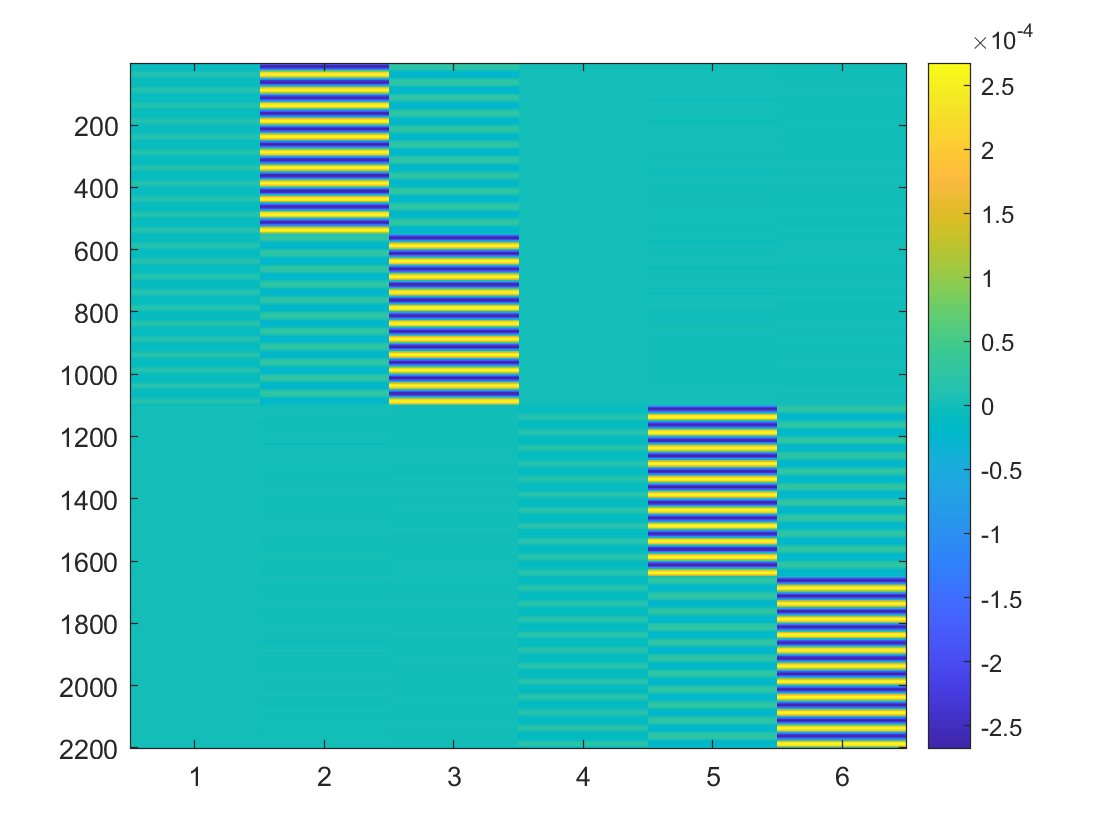


imagesc(eqa_all); colorbar

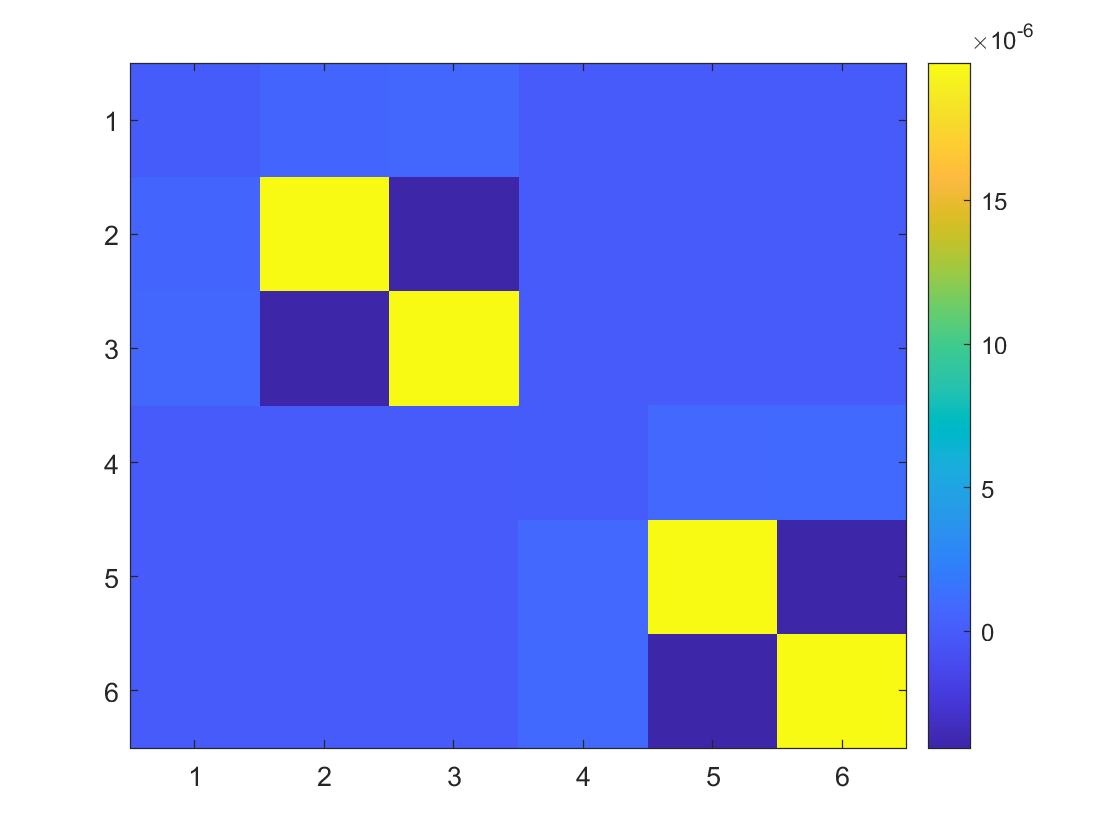

imagesc(eqa_normal); colorbar

cond(eqa_normal)

ans =     2.07264916884791e+003


bbbb = lsqr(eqa_normal, eqb_normal)

lsqr 在解的 迭代 6 处收敛，并且相对残差为 6.6e-07。


bbbb =     1.49964694152276e+000
    78.3444282079723e-006
    181.744741406420e-006
    1.49898623082489e+000
   -106.704406585291e-006
   -17.3468834156203e-006


acos(dot(bbbb(1: 3), pc_a) / (norm(bbbb(1: 3)) * norm(pc_a)))

ans =     97.9238115921695e-006


acos(dot(bbbb(4: 6), pc_b) / (norm(bbbb(4: 6)) * norm(pc_b)))

ans =     105.057388297001e-006


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.037。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0024。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0024。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0024。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.039。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.039。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.039。


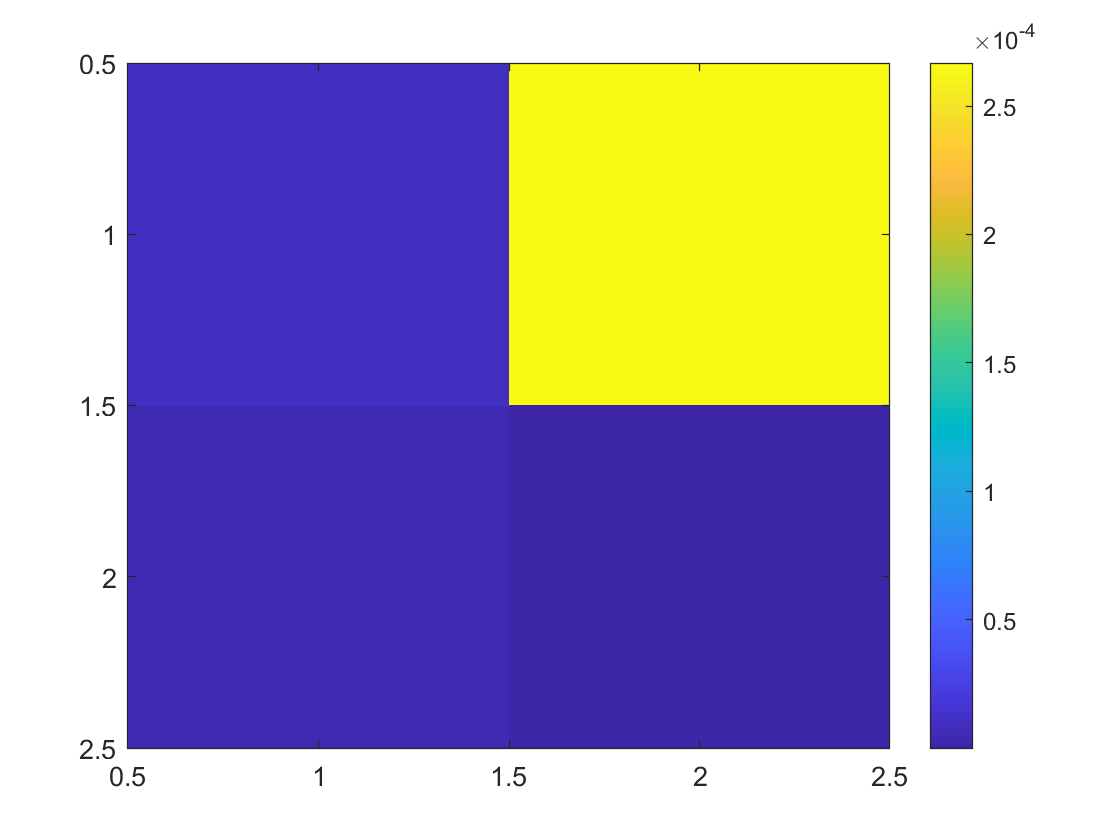

lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.6e-09。


cccc = zeros(6, 1);
cccc([1 2]) = solver_spectral(eqa1, eqb1, [1 2], 0.2);

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.032。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.032。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.032。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0024。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0024。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0024。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.051。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.051。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.051。


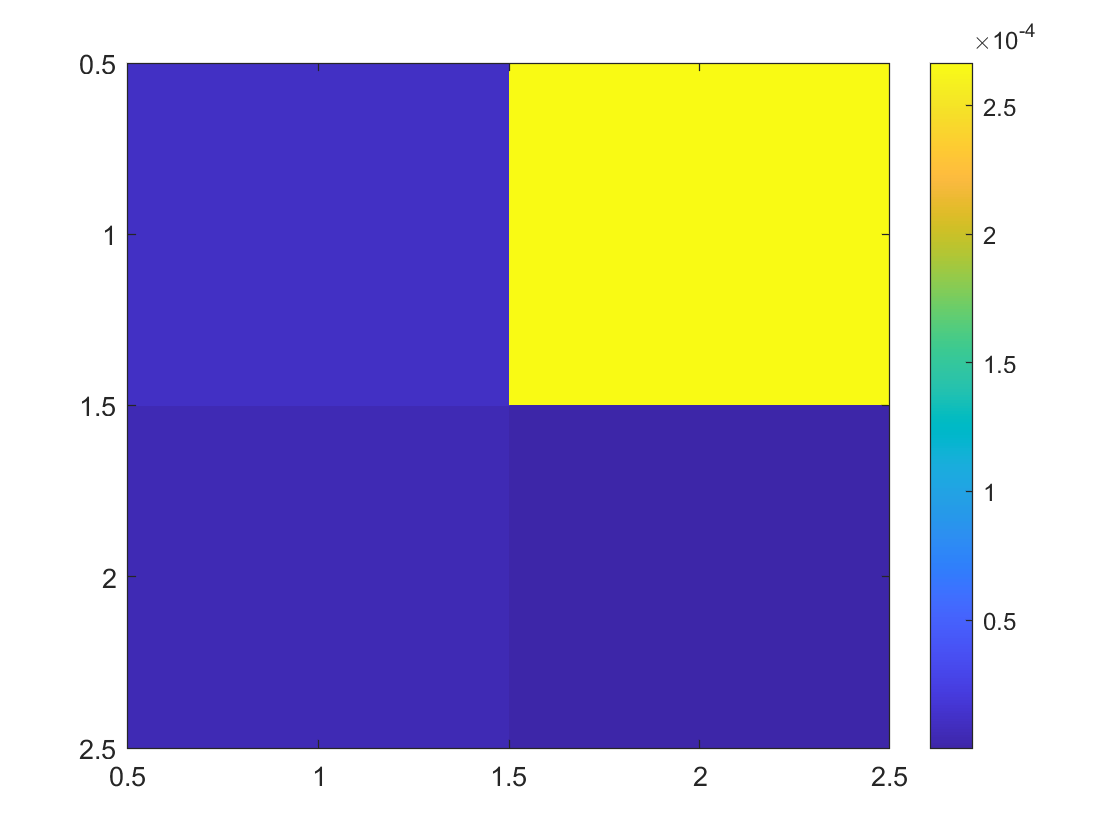

lsqr 在解的 迭代 2 处收敛，并且相对残差为 4.6e-10。


cccc([1 3]) = solver_spectral(eqa2, eqb2, [1 3], 0.2);

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.003。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.003。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.003。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.058。


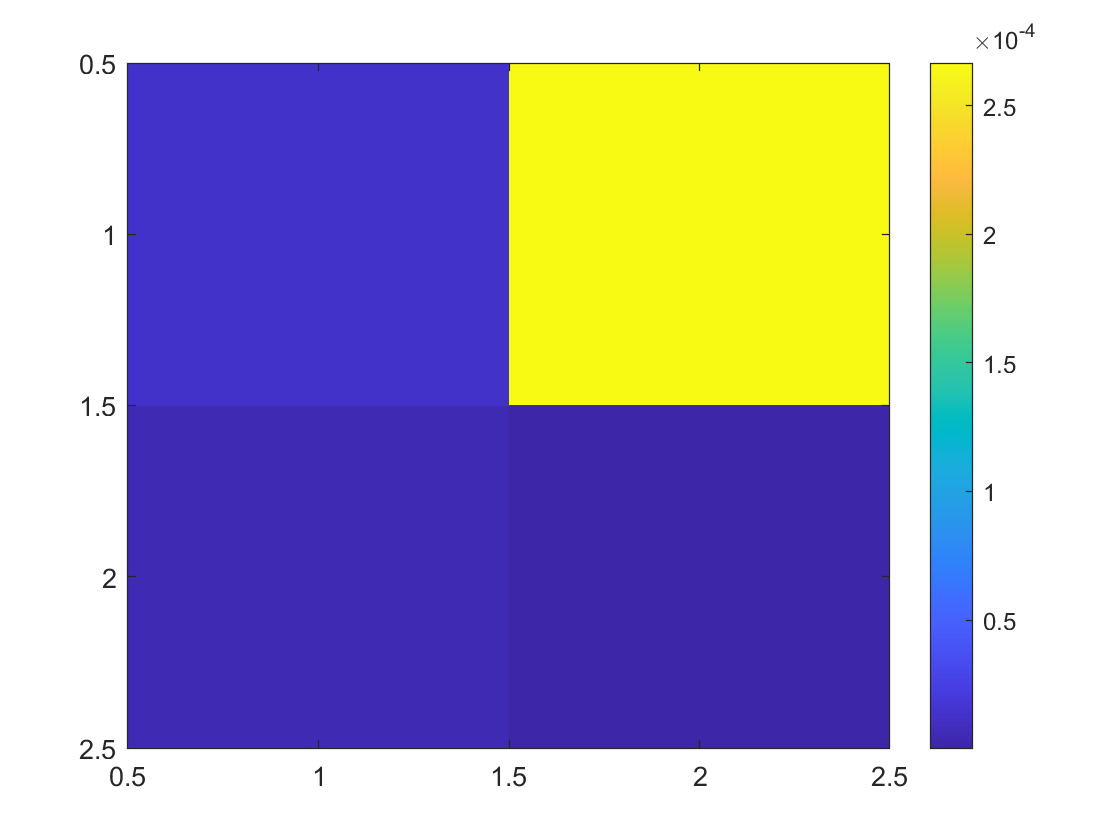

lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.8e-09。


cccc([4 5]) = solver_spectral(eqa3, eqb3, [4 5], 0.2);

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.0025。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.029。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.029。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.029。


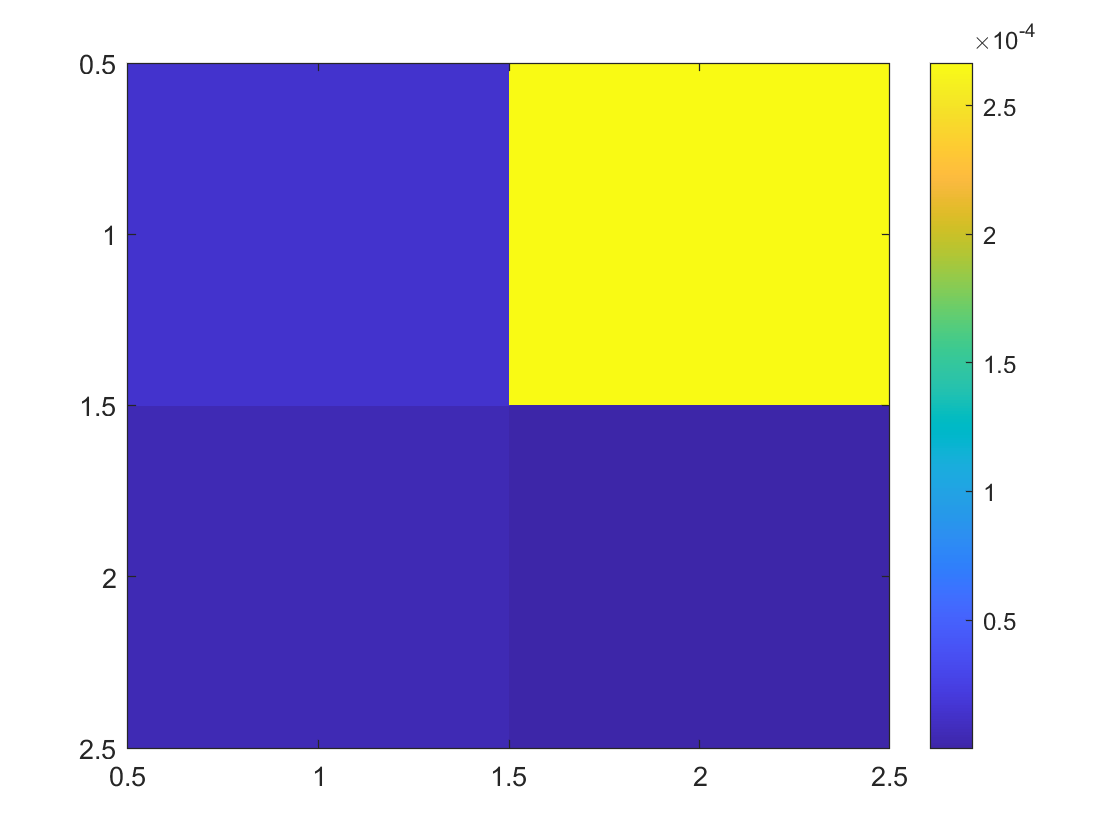

lsqr 在解的 迭代 2 处收敛，并且相对残差为 3.4e-09。


cccc([4 6]) = solver_spectral(eqa4, eqb4, [4 6], 0.2);

cccc

cccc =     1.50043996675533e+000
    60.8466419087170e-006
    140.265882273394e-006
    1.50136524679555e+000
    166.165913872474e-006
   -136.012668399604e-006


acos(dot(cccc(1: 3), pc_b) / (norm(cccc(1: 3)) * norm(pc_b)))

ans =     68.2441378827098e-006


acos(dot(cccc(4: 6), pc_b) / (norm(cccc(4: 6)) * norm(pc_b)))

ans =     144.247732311190e-006
